# Compare tongue and lip fluorescence

This figure 

- Illustrates fluorescence from tongue and lip, with 405/415 and 450

- Shows the reliability of the data as we measured with multiple subjects, multiple levels of excitation lights, different positions on the dorsal tongue and lip

- Compares with de Veld for the 405/415 by fitting his data with a weighted sum of our data (both tongue and lip)

There is great uniformity in the 500-700nm range for the lip.

For the tongue there is uniformity from 500-600, but the 600 700 nm range we see the porphyrin and chlorophyll variation.

Finally, we see the curvey data that reflects the blood.  All in one figure.

## Initialize code

ieInit;
wave = 500:700;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
fise_plotDefaults;
subjects = {'Z','B','D','J'};
[T,dataDir] = oeDatabaseCreate;

## Load the lip and tongue data

We load all of the subjects into a single large data set for tongue and another one for lip.  In this case we group the 405 and 415 nm excitation lights.  We put the tongue and lip data, normalized at nWave, on the same graph.

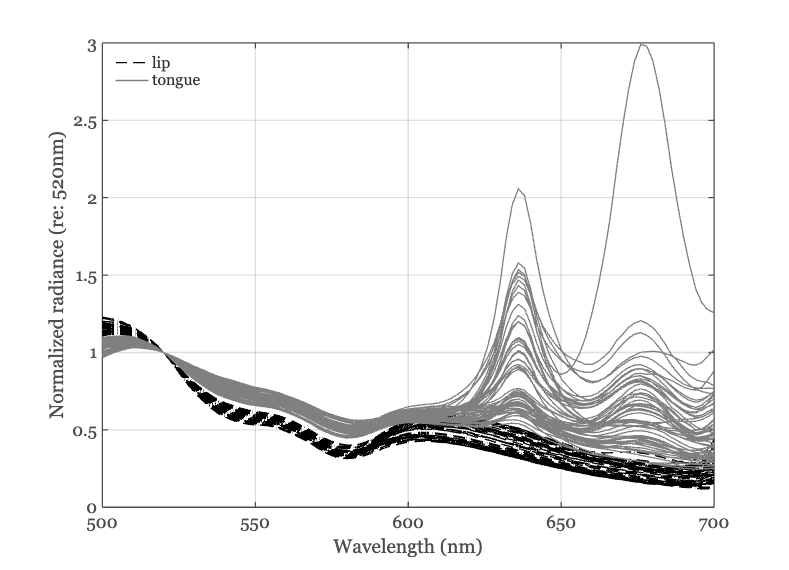

tongueData = [];
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);
    tongueData = cat(2,tongueData,tmp);
end

lipData = [];
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);   
    lipData = cat(2,lipData,tmp);
end 

ieFigure; 
hA = plot(wave,lipData,'k--'); hold on;
hB = plot(wave,tongueData,'Color',[1 1 1]*0.5);
grid on; 
xlabel('Wavelength (nm)'); ylabel('Normalized radiance (re: 520nm)');
lgn = legend([hA(1),hB(1)],{'lip','tongue'},'Location','northwest');
% set(gca,'ylim',[0 3]);
exportgraphics(gcf,'All-405-415.png','Resolution',150);

### 450 nm excitation light

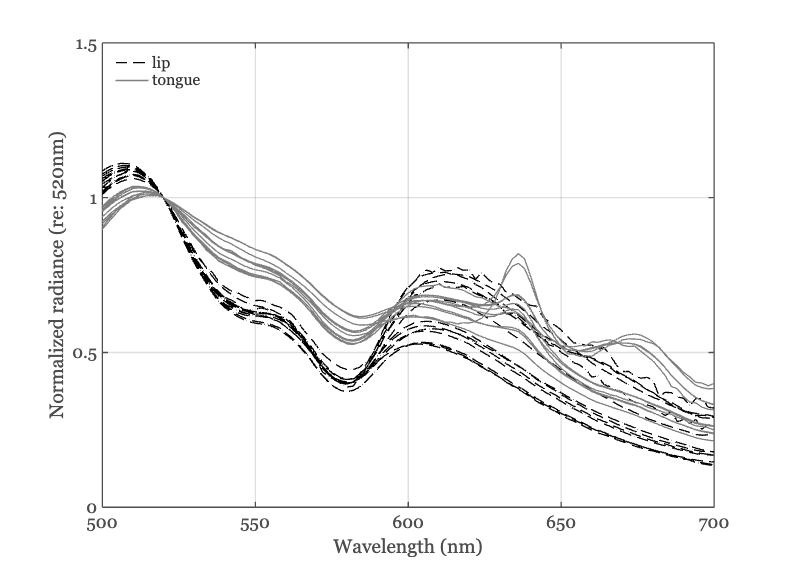

tongueData450 = [];
for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',450);
    tmp  = oeReadFiles(files450,'normalized wave',normWave,'wave',wave); 
    tongueData450 = cat(2,tongueData450,tmp);
end

lipData450 = [];
for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',450);
    tmp  = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);       
    lipData450 = cat(2,lipData450,tmp);
end 

ieFigure; 
hA = plot(wave,lipData450,'k--'); hold on;
hB = plot(wave,tongueData450,'Color',[1 1 1]*0.5);
grid on; 
xlabel('Wavelength (nm)'); ylabel('Normalized radiance (re: 520nm)');
set(gca,'ylim',[0 1.5]);
lgn = legend([hA(1),hB(1)],{'lip','tongue'},'Location','northwest');
exportgraphics(gcf,'All-450.png','Resolution',150);

## Comparison with de Veld data

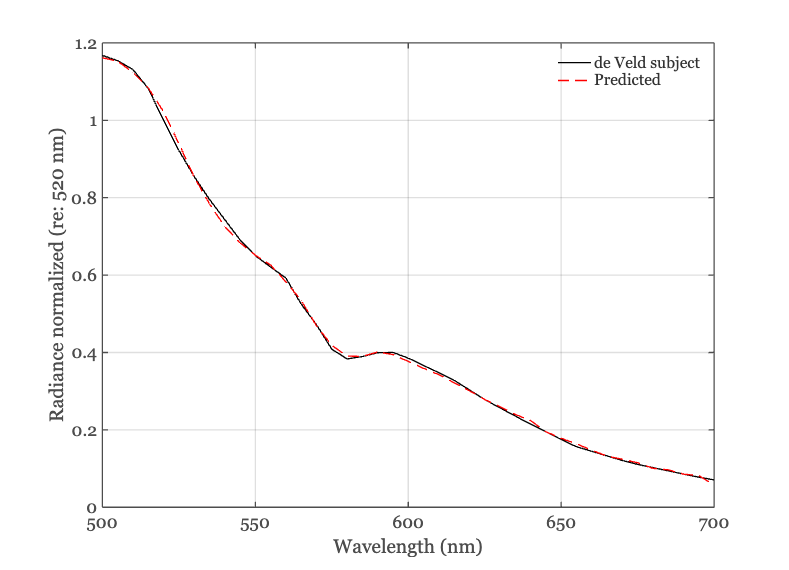

waves = 500:5:700;
veldCheek = ieReadSpectra('CheekVeld2003.mat',waves); 
veldCheek = veldCheek/veldCheek(waves==520);

eWave = 405;
files405 = ieTableGet(T,...
    'substrate','lip', ...
    'ewave',eWave);
files415 = ieTableGet(T,...
    'substrate','lip', ...
    'ewave',eWave);
lipFiles = cat(1,files405,files415);

data405 = oeReadFiles(lipFiles,'waves',waves,'normalized wave',520);
wgts = pinv(data405)*veldCheek;
veldCheekP = data405*wgts;

ieFigure;
plot(waves,veldCheek,'k-',waves,veldCheekP,'r--');
grid on;
legend({'de Veld subject','Predicted'});
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 520 nm)');
exportgraphics(gcf,fullfile(oeTongueLipRootPath,'figures','develd-lip.png'),'Resolution',150);

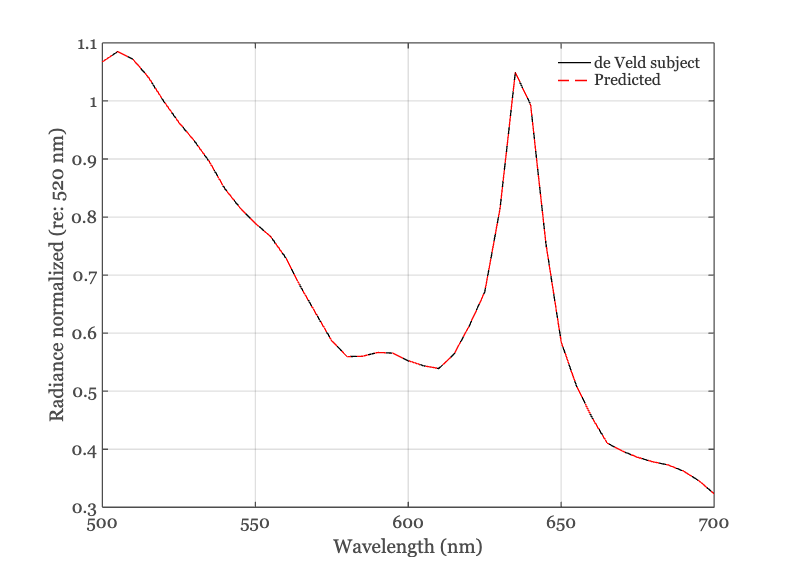

veldTongue = ieReadSpectra('TongueVeld2003.mat',waves); 

% Normalize to 520 nm
veldTongue = veldTongue/veldTongue(waves== 520);

eWave = 405;
files405 = ieTableGet(T,...
    'substrate','tongue', ...
    'ewave',eWave);
eWave = 415;
files415 = ieTableGet(T,...
    'substrate','tongue', ...
    'ewave',eWave);
tongueFiles = cat(1,files405,files415);

data405 = oeReadFiles(tongueFiles,'waves',waves,'normalized wave',520);
wgts = pinv(data405)*veldTongue;
veldTongueP = data405*wgts;

ieFigure;
plot(waves,veldTongue,'k-',waves,veldTongueP,'r--');
grid on;
legend({'de Veld subject','Predicted'});
xlabel('Wavelength (nm)'); ylabel('Radiance normalized (re: 520 nm)');
exportgraphics(gcf,fullfile(oeTongueLipRootPath,'figures','develd-tongue.png'),'Resolution',150);